# 第四章 频域处理

## 计算 DFT

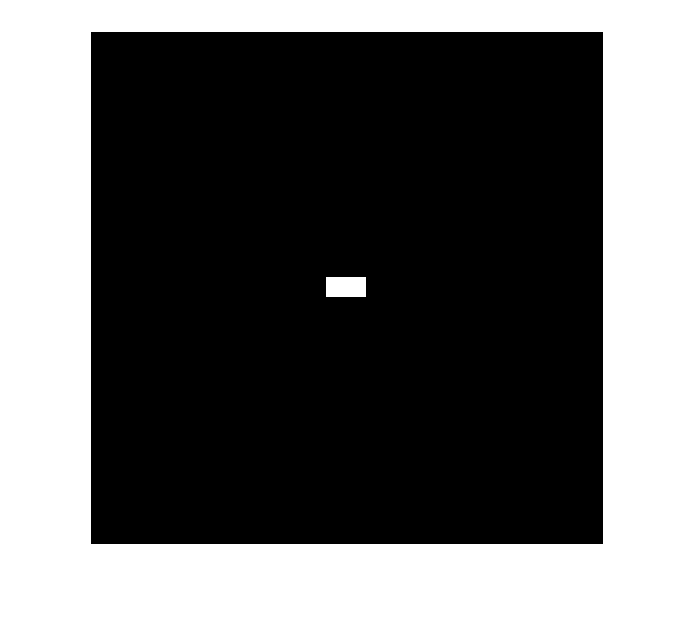

f = imread('./DIP-Ex/pic/dipum_images_ch04/Fig0403(a)(image).tif');
imshow(f);

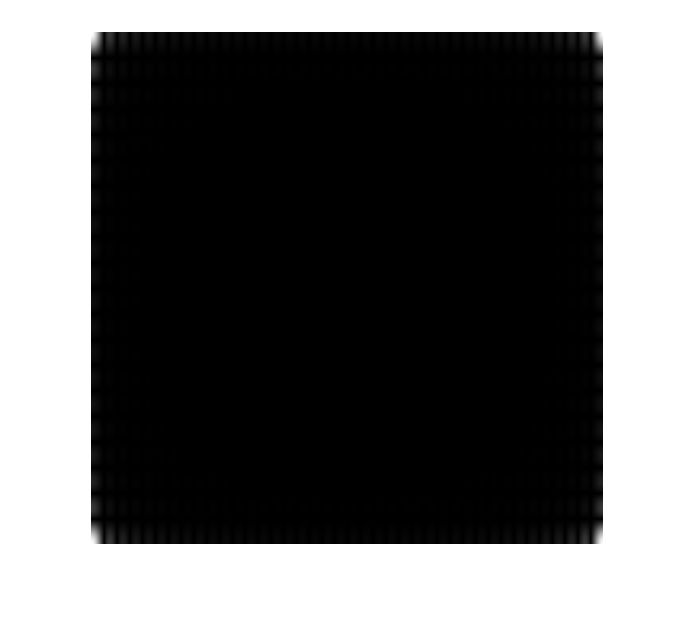

% 要进行傅里叶变换了，还是快速傅里叶
F = fft2(f);
S = abs(F); % 计算频谱，也就是实部虚部平方和
imshow(S, []); % 可以注意到频谱亮点在四周

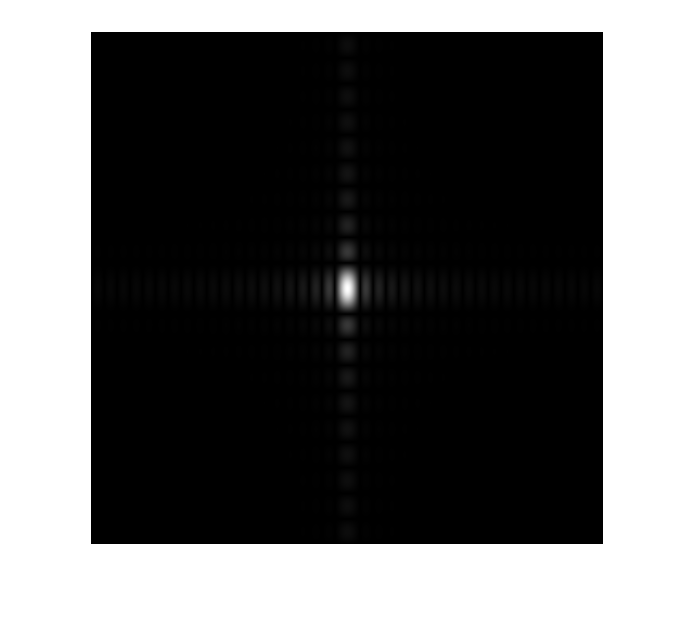

% 错误的 Fc = fftshift(f); % 变换原点移动到中心，类似 (-1)^(x+y), 但输入的是变换后的频率
% 可以看到亮点居中了
Fc = fftshift(F);
imshow(abs(Fc), []); % [] 拿来什么意思 imshow(abs(Fc)) 就会出问题

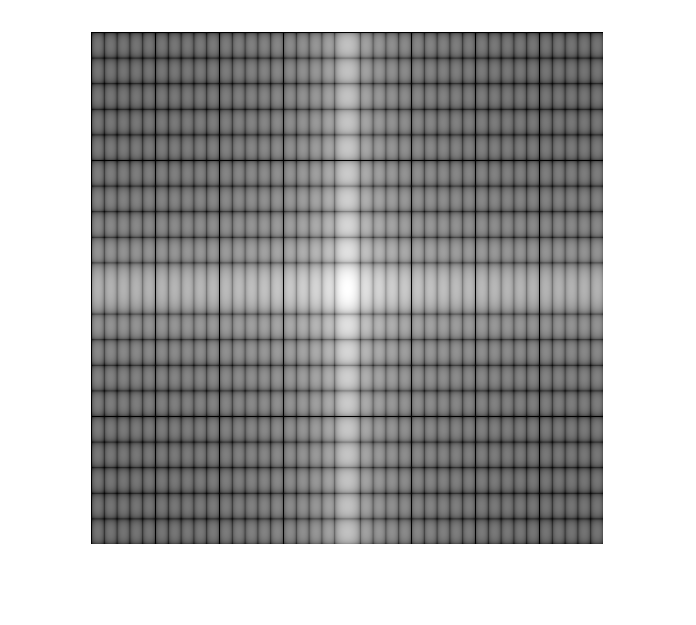

% S2 = log(1 + mat2gray(Fc)); 这是错误的，我是想增强频谱图，不是傅里叶变换频率
S2 = log(1 + abs(Fc));
figure;
imshow(S2, []);

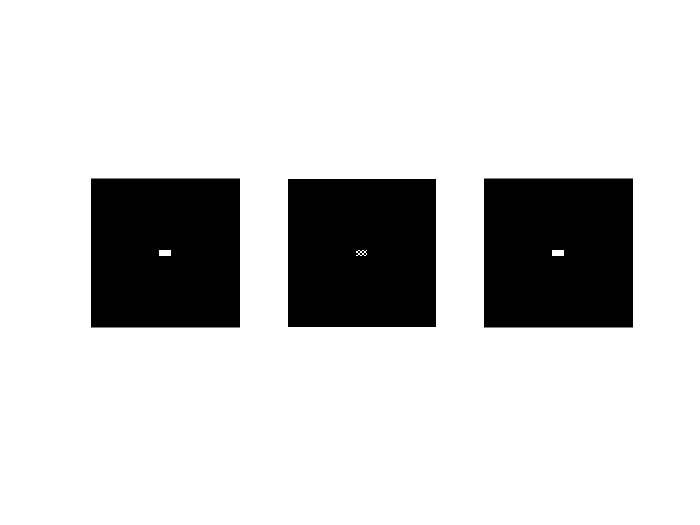

% 再用ifftshift 把居中颠倒，或者用于把中心转回矩形左上角
% ifft2 傅里叶逆变换，输入的是原始的傅里叶变换
f1 = ifft2(F);
figure;
subplot(1, 3, 1), imshow(f1), subplot(1, 3, 2), imshow(ifft2(Fc)), subplot(1, 3, 3), imshow(real(ifft2(F)));

## 频率滤波

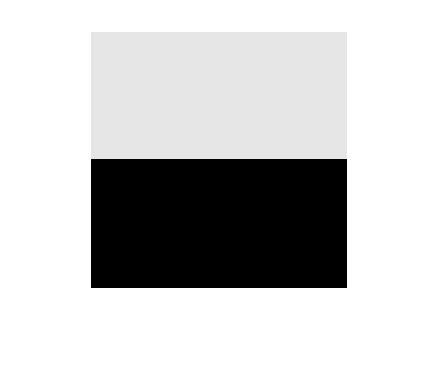

% 空间域卷积 - 频率域相乘
% 例4.1 填充与否的滤波效果
f = imread('./DIP-Ex/pic/dipum_images_ch04/Fig0405(a)(square_original).tif');
figure;
imshow(f); % 256 * 256

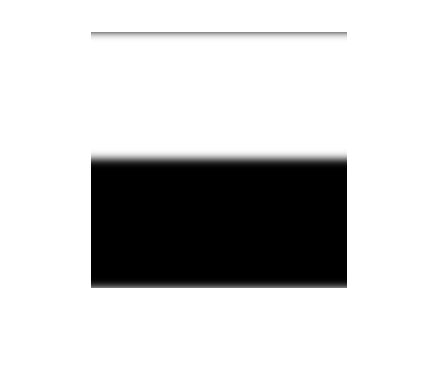

[M, N] = size(f);
F = fft2(f); %傅里叶
% 高斯低通滤波器
sig = 10;
H = lpfilter('gaussian', M, N, sig);
G = H .* F; % 频率域滤波
fi = ifft2(G);
% 可以发现，未填充的垂直部分没有模糊，而水平部分模糊了
% 滤波器(空间表示)处于一个亮暗周期的图像上卷积，自然会模糊(周期性是因为 DFT，但是在这里我们还是用空间域解释)，垂直部分不太理解
% 具体看图 4.32
imshow(real(fi), []); 

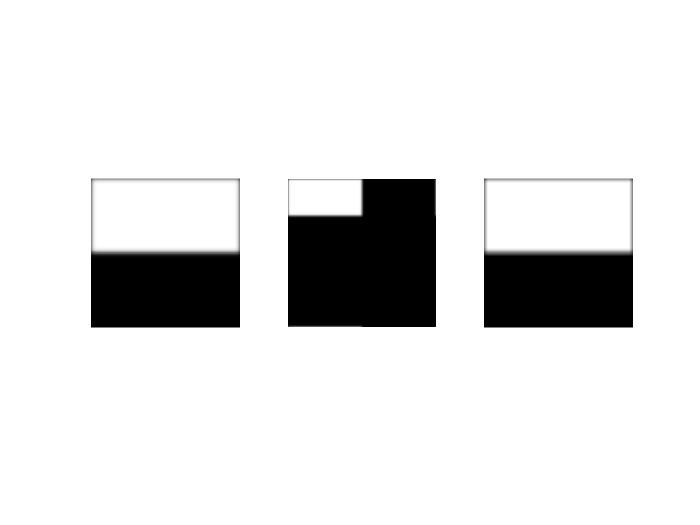

PQ = paddedsize(size(f)); % 512 * 512
Fp = fft2(f, PQ(1), PQ(2)); % 经过填充
sig = 10;
Hp = lpfilter('gaussian', PQ(1), PQ(2), 2 * sig); % 频率域中使用填充，滤波器和图像大小要相同 PQ(1) * PQ(2)
Gp = Fp .* Hp;
gp = real(ifft2(Gp)); % 逆变换
gpc = gp(1:size(f, 1), 1:size(f, 2)); % 裁剪，不然就是下右二2图(类似空间滤波结果
figure;
h = fspecial('gaussian', 15, 7);
gs = imfilter(f, h); % 在空间滤波
subplot(1, 3, 1), imshow(gpc, []), subplot(1, 3, 2), imshow(gp, []), subplot(1, 3, 3), imshow(gs, []); % 水平和垂直都有模糊边框

## DFT 滤波基本步骤

## 空间滤波器获得频率滤波器

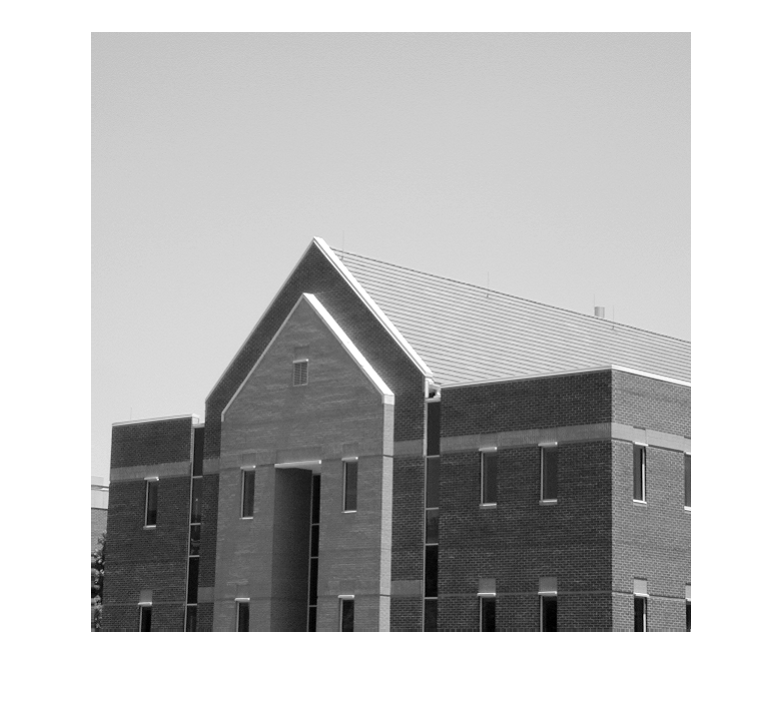

% 基本方法，对空间滤波器进行傅里叶 H = fft2(h, PQ(1), PQ(2))
% 例 4.2
f = imread('./DIP-Ex/pic/dipum_images_ch04/Fig0409(a)(bld).tif');
figure;
imshow(f);

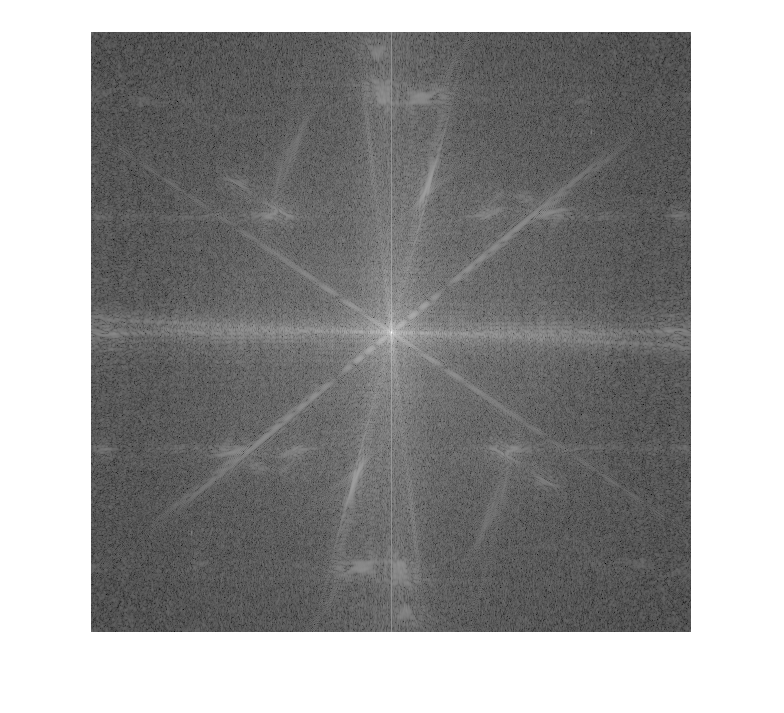

F = fft2(f); % 光这个不行, 结果是黑色，这时候就要考虑是不是要增强频谱图像，而且要不要居中？
S = fftshift(log(1 + abs(F)));
figure;
imshow((S), []);

h = fspecial('sobel'); % 默认横向的sobel 算子，所以后头的图中会发现横边缘被增强
h

h =      1     2     1
     0     0     0
    -1    -2    -1


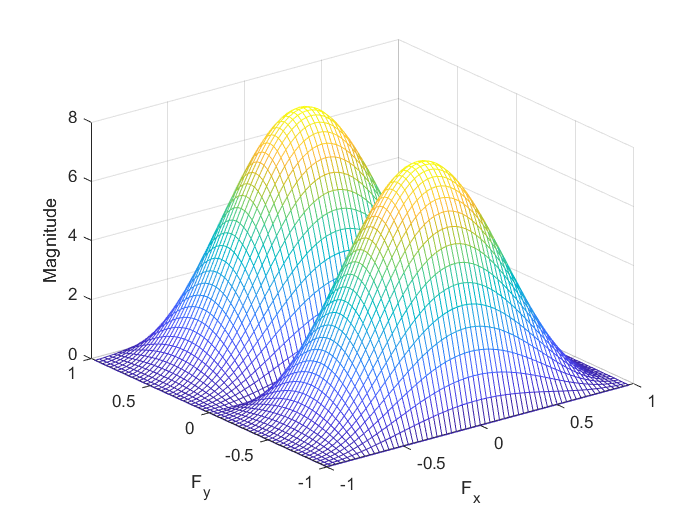

figure;
freqz2(h);

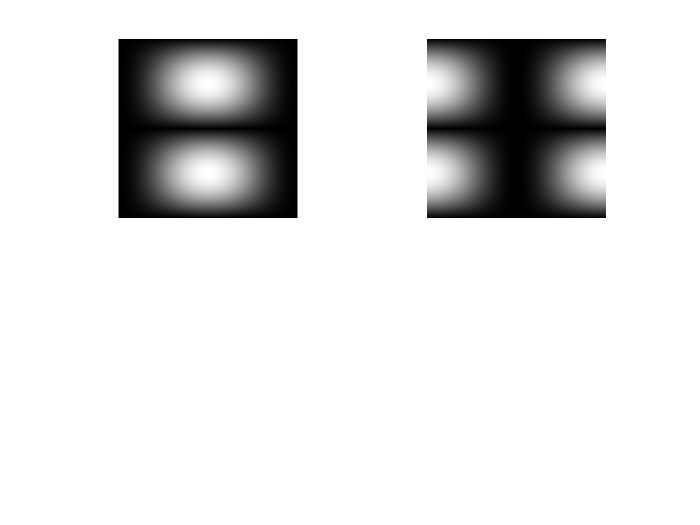

PQ = paddedsize(size(f));
H = freqz2(h, PQ(1), PQ(2)); % freqz2 可以生成一个频率滤波
H1 = ifftshift(H); % 输入中心化过的傅里叶变换，输出逆中心化(原点位于左上角
figure;
% 明显中心化过
%subplot(1, 2, 1), freqz2(abs(H)), subplot(1, 2, 2), freqz2(abs(H1));
subplot(2, 2, 1), imshow(abs(H), []), subplot(2, 2, 2), imshow(abs(H1), []); 

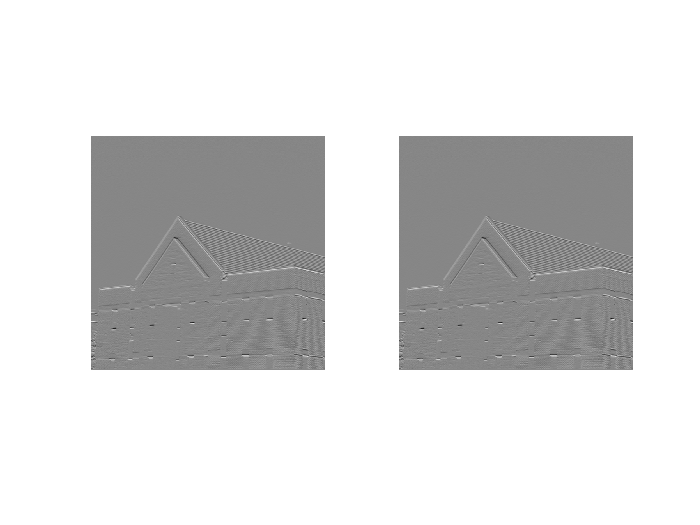

% 空间域滤波，sobel 算子
gs = imfilter(double(f), h);
% 频率域滤波，sobel 算子对应的频率函数
gf = dftfilt(f, H1);
figure;
% 发现一致
subplot(1, 2, 1), imshow(gs, []), subplot(1, 2, 2), imshow(gf, []);

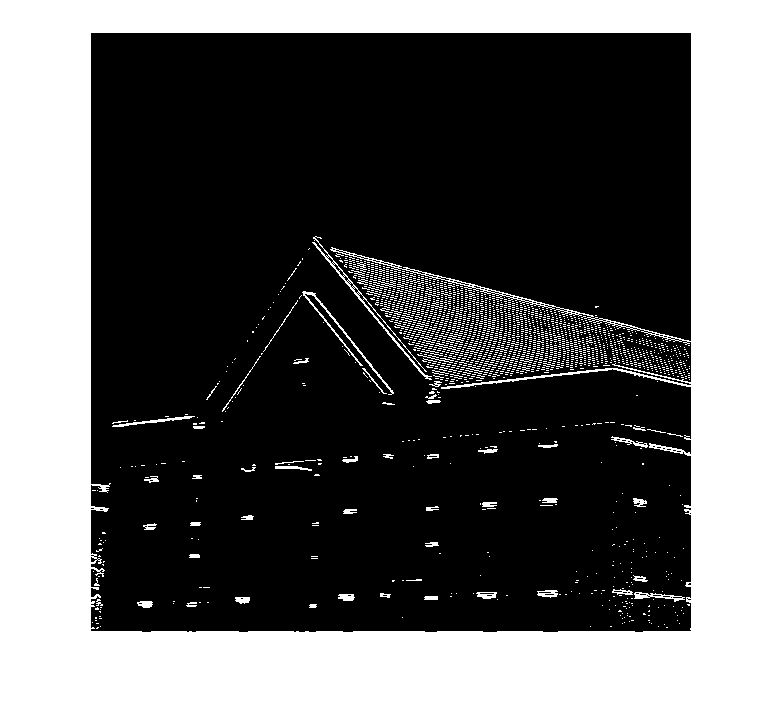

% 创建二值图像，看边缘
figure;
imshow(abs(gs) > 0.2 * abs(max(gs(:))));

figure;
imshow(abs(gf) > 0.2 * abs(max(gf(:))));

## 在频率域中生成滤波器

% 解释 dftuv 的作用，尝试读懂代码，注意 meshgrid 的用法
[U, V] = dftuv(8, 5);
U

U =      0     0     0     0     0
     1     1     1     1     1
     2     2     2     2     2
     3     3     3     3     3
     4     4     4     4     4
    -3    -3    -3    -3    -3
    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1


V

V =      0     1     2    -2    -1
     0     1     2    -2    -1
     0     1     2    -2    -1
     0     1     2    -2    -1
     0     1     2    -2    -1
     0     1     2    -2    -1
     0     1     2    -2    -1
     0     1     2    -2    -1


D = U.^2 + V.^2;
D % 这就是与左上角的距离矩阵了，最大距离位置就是矩阵中心

D =      0     1     4     4     1
     1     2     5     5     2
     4     5     8     8     5
     9    10    13    13    10
    16    17    20    20    17
     9    10    13    13    10
     4     5     8     8     5
     1     2     5     5     2


fftshift(D) % 很明显，将中心转移到矩阵中心了

ans =     20    17    16    17    20
    13    10     9    10    13
     8     5     4     5     8
     5     2     1     2     5
     4     1     0     1     4
     5     2     1     2     5
     8     5     4     5     8
    13    10     9    10    13


## 低通频率滤波器

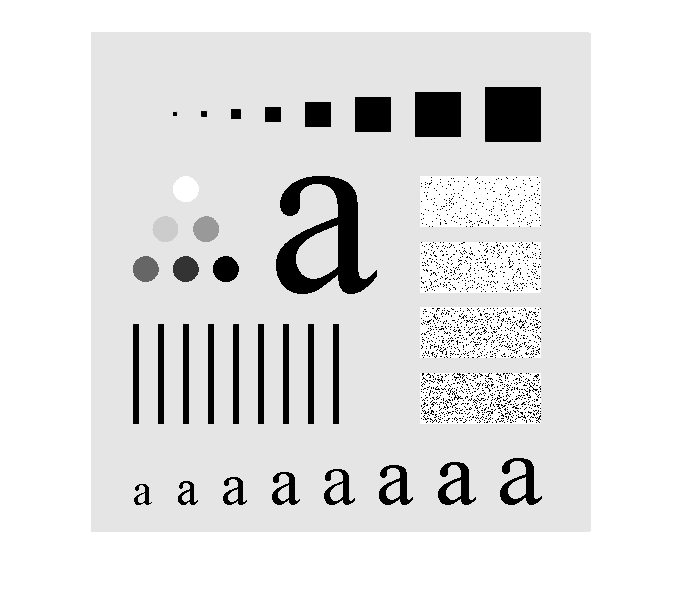

% 例 4.4
f = imread('./DIP-Ex/pic/dipum_images_ch04/Fig0413(a)(original_test_pattern).tif');
figure;
imshow(f);

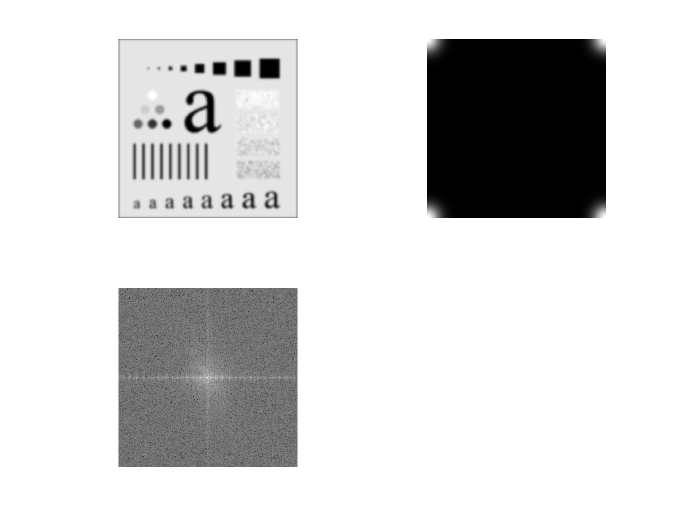

PQ = paddedsize(size(f));
[U, V] = dftuv(PQ(1), PQ(2));
D0 = 0.05 * PQ(2); % 
F = fft2(f, PQ(1), PQ(2)); % 变换
H = exp(-(U .^ 2 + V .^ 2) ./ (2 * D0 ^ 2)); % 高斯低通滤波器
g = dftfilt(f, H);
figure;
% H 非中心化了, F 是傅里叶变化后的图像
subplot(2, 2, 1), imshow(g, []), subplot(2, 2, 2), imshow((H), []);
subplot(2, 2, 3), imshow(log(1 + abs(fftshift(F))), []);

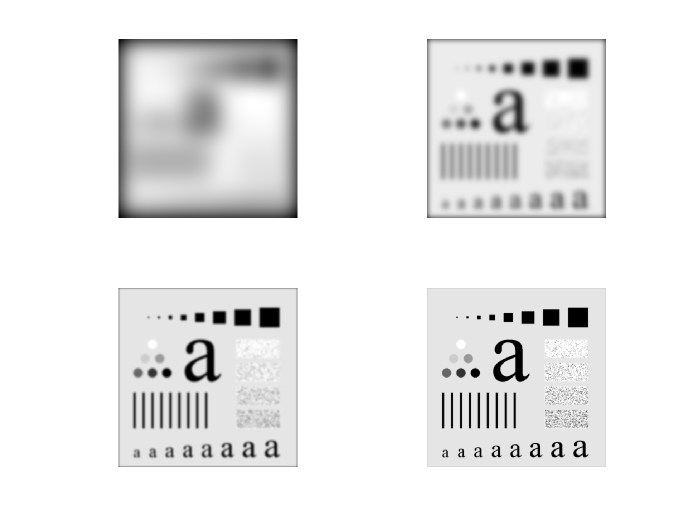

% 比较一下 D0 大小的滤波效果
H1 = exp(-(U .^ 2 + V .^ 2) ./ (2 * 5 ^ 2));
H2 = exp(-(U .^ 2 + V .^ 2) ./ (2 * 20 ^ 2));
H3 = exp(-(U .^ 2 + V .^ 2) ./ (2 * 60 ^ 2));
H4 = exp(-(U .^ 2 + V .^ 2) ./ (2 * 160 ^ 2));
figure;
% D0 越大，频率域越宽，通过频率越多，高频衰减变小，空间核变小，模糊效果越小
subplot(2, 2, 1), imshow(dftfilt(f, H1), []), subplot(2, 2, 2), imshow(dftfilt(f, H2), []);
subplot(2, 2, 3), imshow(dftfilt(f, H3), []), subplot(2, 2, 4), imshow(dftfilt(f, H4), []);

## 线框图和表面图

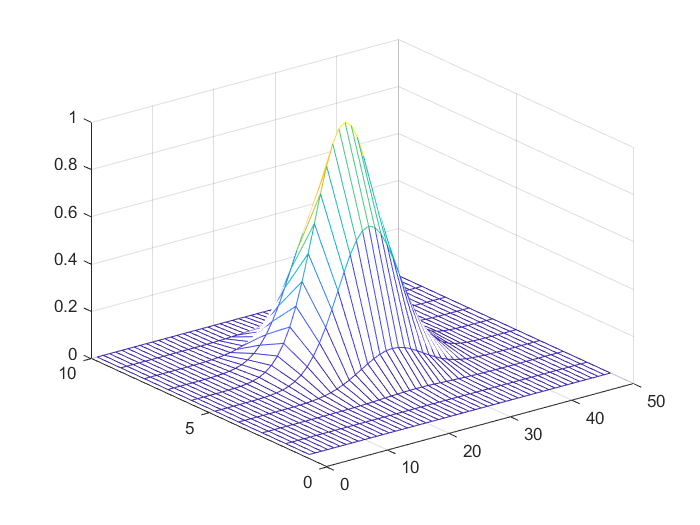

% 例 4.5 绘制线框图
H = fftshift(lpfilter('gaussian', 500, 500, 50));
figure;
mesh(H(1:50:500, 1:10:500));

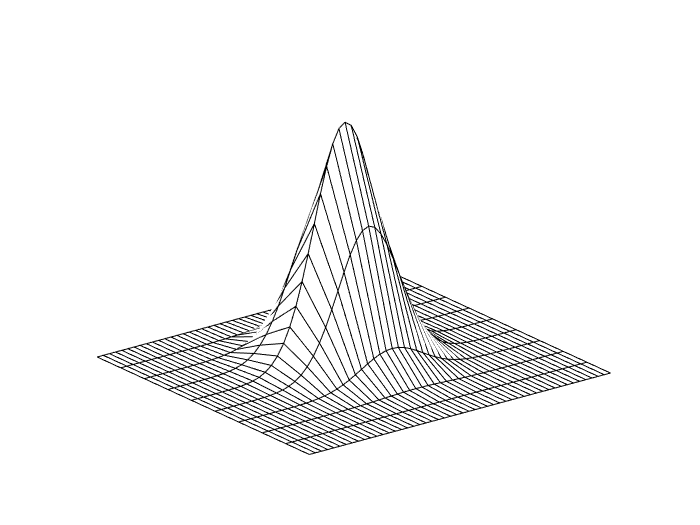

figure;
mesh(H(1:50:500, 1:10:500));
colormap([0 0 0]);
% view(-25, 0); 仰角为 0
grid off;
axis off;

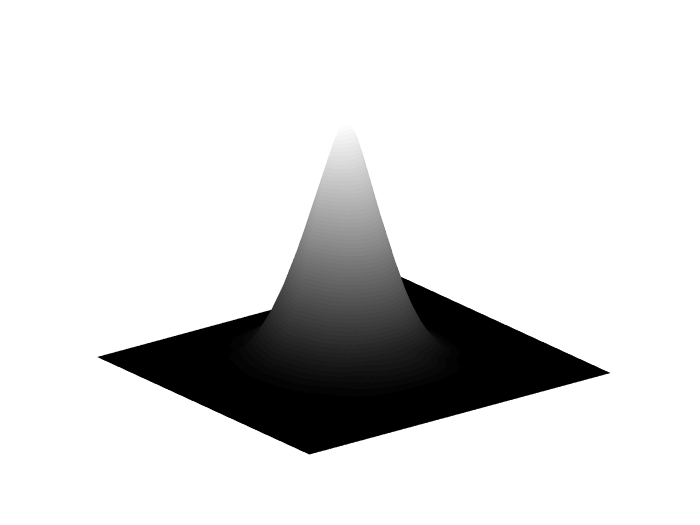

figure;
surf(H(1:50:500, 1:10:500)); % 表面图
colormap(gray);
shading interp; % 删除网格线
grid off, axis off;

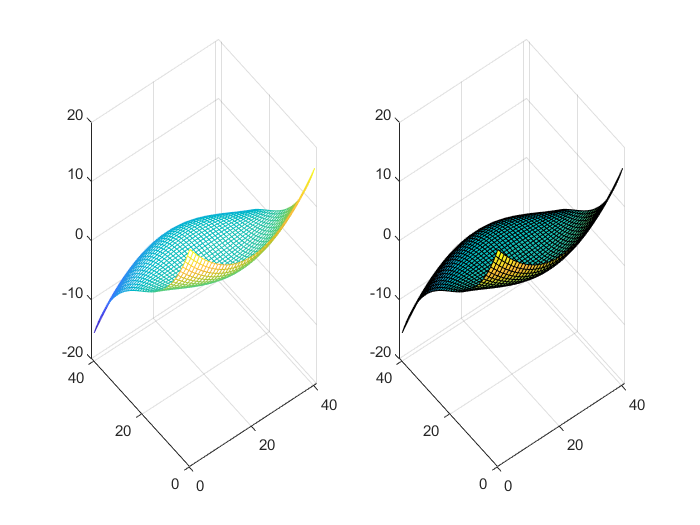

% 画二元函数
[Y, X] = meshgrid(-2:0.1:2, -2:0.1:2);
Z = X .* (-X .^ 2 - Y .^ 2);
figure;
subplot(1, 2, 1), mesh(Z), subplot(1, 2, 2), surf(Z);

## 锐化频率滤波器

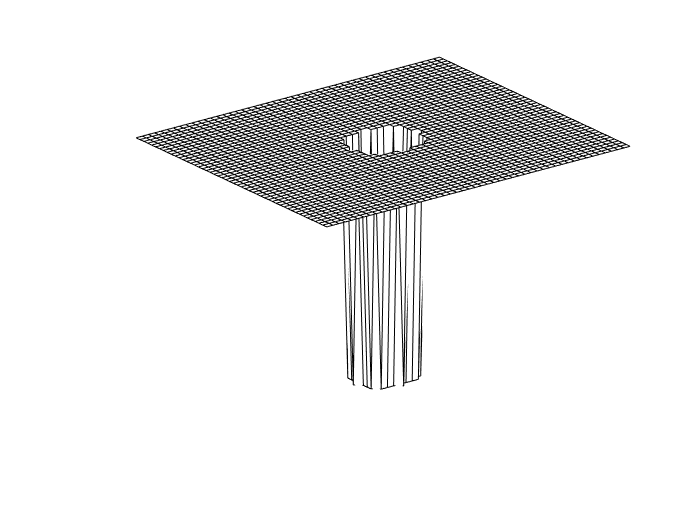

% 1 - lp = hp 详见 hpfilter
H = fftshift(hpfilter('ideal', 500, 500, 50));
figure;
mesh(H(1:10:500, 1:10:500));
colormap([0, 0, 0]);
view(-37, 30);
grid off, axis off;

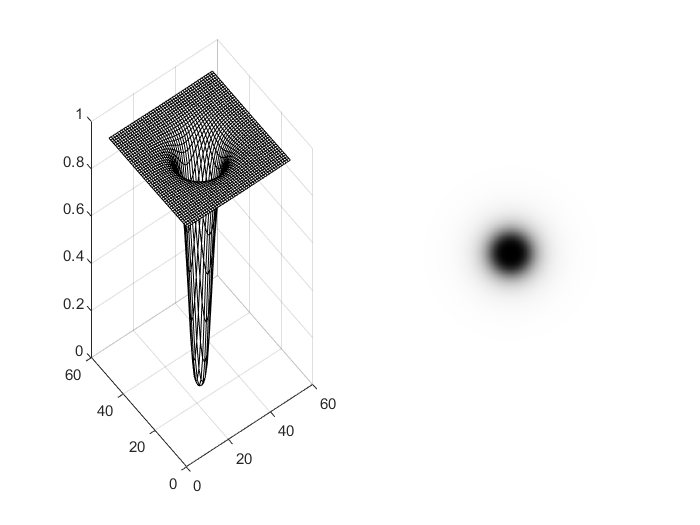

H = fftshift(hpfilter('btw', 500, 500, 50, 2)); % 2 阶巴特沃斯滤波器
figure;
subplot(1, 2, 1);
mesh(H(1:10:500, 1:10:500));
colormap([0, 0, 0]);
view(-37, 30);
%grid off, axis off;
subplot(1, 2, 2);
subplot(1, 2, 2);
imshow(H, []);

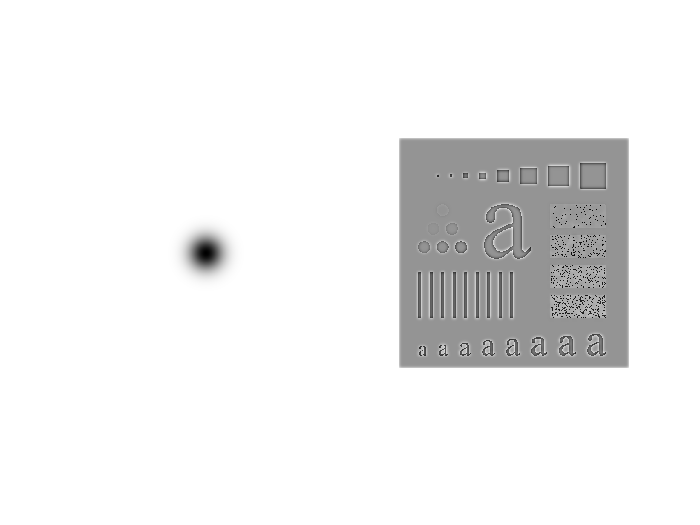

% 例 4.7 高通滤波
% PS 之前学习过空间域得到频率域的滤波器，所以传入 dftfilt 需要经过傅里叶，但是这里的滤波器都是频率域内的滤波器
% 所以此处 dftfilt 直接传入 H 即可，注意区别
f = imread('./DIP-Ex/pic/dipum_images_ch04/Fig0413(a)(original_test_pattern).tif');
PQ = paddedsize(size(f)); % 要填充后滤波
D0 = 0.05 * PQ(2);
H = hpfilter('gaussian', PQ(1), PQ(2), D0); % 中心在左上角，并非矩形中心
g = dftfilt(f, H);
figure;
subplot(1, 2, 1);
imshow(fftshift(H), []); % 滤波器的图像化
subplot(1, 2, 2);
imshow(g, []); % 背景失去色调，接下来用高通强调滤波处理

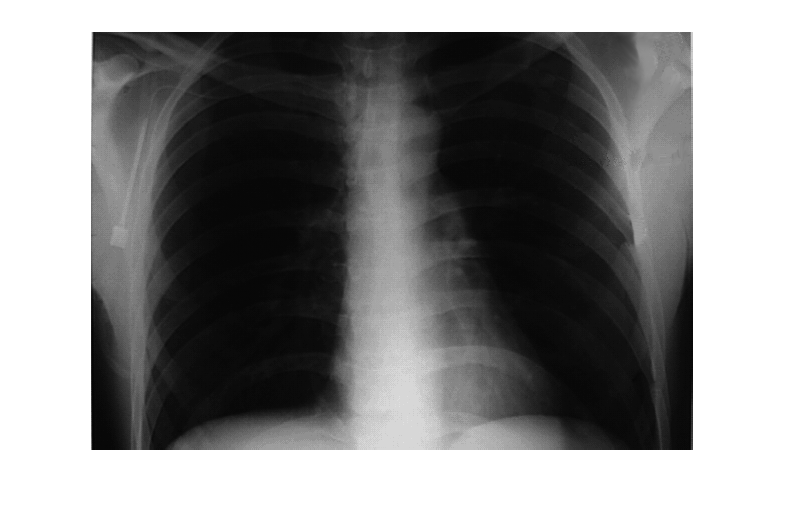

% 高通强调滤波
% 例 4.8 高频强调滤波 + 直方图均衡
f = imread('./DIP-Ex/pic/dipum_images_ch04/Fig0419(a)(chestXray_original).tif');
figure;
imshow(f);

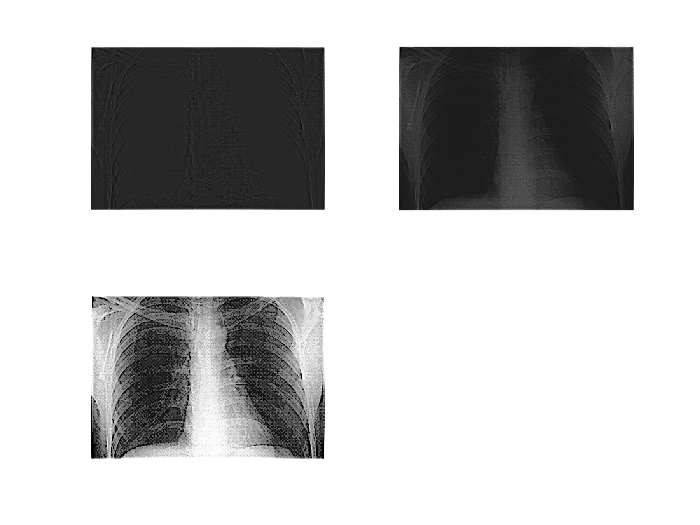

PQ = paddedsize(size(f)); % 要填充
D0 = 0.05 * PQ(2);
% 高通巴特沃斯 2 阶
HBW = hpfilter('btw', PQ(1), PQ(2), D0, 2);
a = 0.5;
b = 2;
H = a + b * HBW; % 高通强调滤波公式
gbw = dftfilt(f, HBW); % 高通巴特沃斯滤波，由于背景色占多，会效果很差
ghf = dftfilt(f, H);
ghe = histeq(mat2gray(ghf), 256); % ghf 明显不太明显，需要对比度增强，直方图均衡, 注意映射到 0~1
figure;
subplot(2, 2, 1);
imshow(gbw, []);
subplot(2, 2, 2);
imshow(ghf, []);
subplot(2, 2, 3);
imshow(ghe, []);

## 函数区域

% fft 执行时间取决于 P Q 素因子数量，P Q 为 2 的幂速度更快
% 傅里叶变换函数支持填充，所以需要一个计算填充的函数

function PQ = paddedsize(AB, CD, PARAM) % AB 是 [1, 2] 这样的数组, 返回的也是 [a, b] 但 a b 代表了要填充的长度
    if nargin == 1
        PQ = 2 * AB; % 两幅图像都是 M * N 自然填充大小直接乘 2 就可以。
    % 说明 AB, CD 都有了
    elseif nargin == 2 & ~ischar(CD)
        PQ = AB + CD - 1;
        PQ = 2 * ceil(PQ / 2); % PQ 的元素起码要不小于 AB + CD - 1，原理在于避免折叠误差
    elseif nargin == 2
        m = max(AB);
        P = 2 ^ nextpow2(2 * m); % 返回最小的比 2m 大的 2 的指数幂
        PQ = [P, P];
    end
end

% 高通滤波器
function H = hpfilter(type, M, N, D0, n)
    if nargin == 4
        n = 1;
    end
    Hlp = lpfilter(type, M, N, D0, n);
    H = 1 - Hlp;
end

% 低通滤波器
function [H, D] = lpfilter(type, M, N, D0, n)
    % LPFILTER Computes frequency domain lowpass filters
    %   H = LPFILTER(TYPE, M, N, D0, n) creates the transfer function of a
    %   lowpass filter, H, of the specified TYPE and size (M-by-N). To view the
    %   filter as an image or mesh plot, it should be centered using H =
    %   fftshift(H)
    %   Valid value for TYPE, D0, and n are:
    %   'ideal' Ideal lowpass filter with cutoff frequency D0. n need not be
    %           supplied. D0 must be positive.
    %   'btw'   Butterworth lowpass filter of order n, and cutoff D0. The
    %           default value for n is 1.0. D0 must be positive.
    %   'gaussian'Gaussian lowpass filter with cutoff (standard deviation) D0.
    %           n need not be supplied. D0 must be positive.
    %
    % 得到指定类型的低通滤波器
    
    % Use function dftuv to set up the meshgrid arrays needed for computing the
    % required distances.
    [U, V] = dftuv(M, N);
    % Compute the distances D(U, V)
    D = sqrt(U.^2 + V.^2);
    % Begin filter computations
    switch type
        case 'ideal'
            H = double(D <= D0);
        % 巴特沃斯
        case 'btw'
            if nargin == 4
                n = 1;
            end
            H = 1 ./ (1 + (D ./ D0) .^ (2 * n));
        case 'gaussian'
            H = exp(-(D .^ 2) ./ (2 * (D0 ^ 2)));
        otherwise
            error('Unkown filter type.')
    end
end

function [U, V] = dftuv(M, N)
    % DFTUV Computes meshgrid frequency matrices.
    % [U, V] = DFTUV(M, N) computes meshgrid frequency matrices U and V. U and
    % V are useful for computing frequency-domain filter functions that can be
    % used with DFTFILT. U and V are both M-by-N.
    % more details to see the textbook Page 93
    %
    % [U，V] = DFTUV（M，N）计算网格频率矩阵U和V。 U和V对于计算可与DFTFILT一起使用的
    % 频域滤波器函数很有用。 U和V都是M-by-N。更多细节见冈萨雷斯教材93页
    
    % Set up range of variables.
    % 设置变量范围
    u = 0 : (M - 1);
    v = 0 : (N - 1);
    
    % Compute the indices for use in meshgrid.
    % 计算网格的索引，即将网络的原点转移到左上角，因为FFT计算时变换的原点在左上角。
    idx = find(u > M / 2);
    u(idx) = u(idx) - M;
    idy = find(v > N / 2);
    v(idy) = v(idy) - N;
    
    % Compute the meshgrid arrays.
    % 计算网格矩阵
    [V, U] = meshgrid(v, u);
end


% 自定义一个 DFT 滤波步骤 频率域滤波
function g = dftfilt(f, H) % f 图像，H 频率滤波器 % 滤波函数 H 不要居中化(参考前头的四角亮的频谱
    % 频率域中使用填充，滤波器和图像大小要相同
    F = fft2(f, size(H, 1), size(H, 2));
    g = real(ifft2(F .* H)); % 逆变换取实部
    g = g(1:size(f, 1), 1:size(f, 2)); % 裁剪到原图大小
end